# **Spectral Clustering of Lagrangian Trajectories **

##  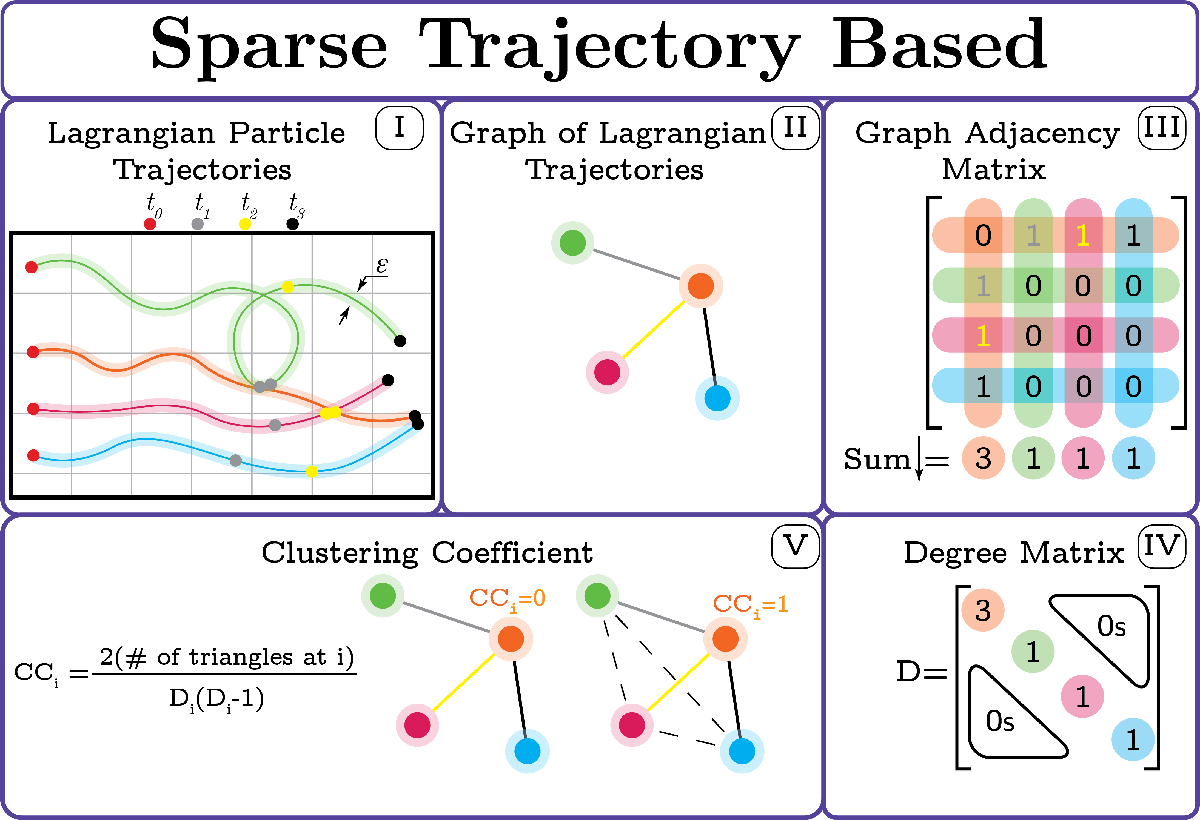

## **Generate the Bickley Jet Flow**

clc, clear all 
[VEC,t] = BICKJET(10,30);

***Show the velocity field***

FlowType = 'BickleyJet';
Sky = 5;
Skx = 5;
Sc = 0.2;

**Figure 1 - The Bickley Jet**

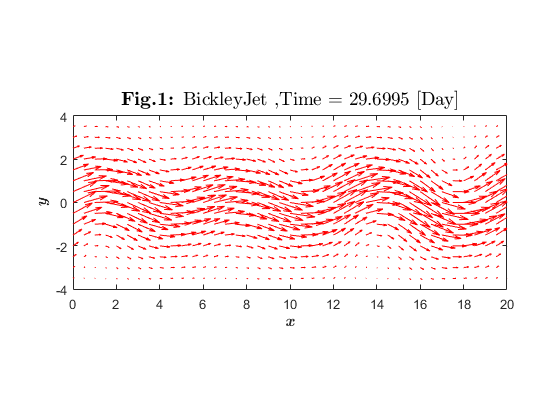

figure
for k = 1 :10: length(VEC)
    quiver(VEC{1}.X(1:Sky:end,1:Skx:end),VEC{1}.Y(1:Sky:end,1:Skx:end),...
        Sc*VEC{k}.U(1:Sky:end,1:Skx:end),Sc*VEC{k}.V(1:Sky:end,1:Skx:end),'r','autoscale','off')
    axis ([0 20 -4 4])
    xlabel('\textit{\textbf{x}}','interpreter','latex','FontSize',12)
    ylabel('\textit{\textbf{y}}','interpreter','latex','FontSize',12)
    title(['\textbf{Fig.1: }',FlowType,'  ,Time = ',num2str(t(k)),' [Day]'],'interpreter','latex','FontSize',14);
    pbaspect([2.5 1 1])
    pause(0.1)
end

## **I - Lagrangian Particle Positions (Trajectories)**

RF = 0.3; 
RES = abs(VEC{1}.X(1,1)-VEC{1}.X(1,2))/RF

RES = 0.3333

[A,I,VECRF,nx,ny] = TN_Lagrang_Traj(VEC,RF,t,FlowType,RES);

## **II & III - Graph Analysis**

***Similarity matrix***

eps =3*RES % Multiplication of RES

eps = 1

[S,A] = TN_Adjacency(A,eps);  

## **IV - Nodal Degree**

DegMat = zeros(ny,nx);
DEG = sum(S);
DegMat(I) = DEG;
RhoEpsilon = sum(double(logical(S)),'all')/(length(I).^2-length(I))

RhoEpsilon = 0.1755

**Figure 2 - Degree contour**

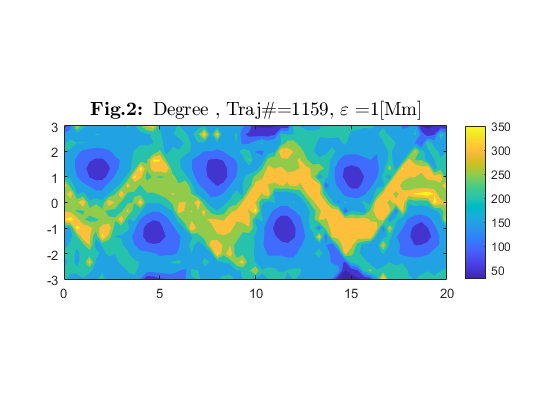

figure
contourf(VECRF.X,VECRF.Y,DegMat,'edgecolor','none');
shading interp
colorbar
title(['\textbf{Fig.2: }','Degree ',', Traj\#=',num2str(size(I,1)),', $\varepsilon$ =',...
    num2str(round(eps,3)),'[Mm]'],'interpreter','latex','FontSize',14);
pbaspect([2.5 1 1])

## **V - Clustering Coefficient **

ci = TN_Clust_Coef(S);
ClusCo = zeros(ny,nx);
ClusCo(I) = ci;

**Figure 3 - Clustering Coefficient**

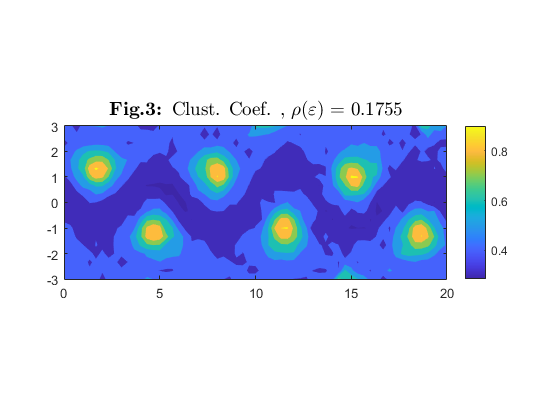

figure
contourf(VECRF.X,VECRF.Y,ClusCo,'edgecolor','none')
shading interp
colorbar
title(['\textbf{Fig.3: }','Clust. Coef. ,  $\rho(\varepsilon)$ = ',...
    num2str(round(RhoEpsilon,4))],'interpreter','latex','FontSize',14)
pbaspect([2.5 1 1])

## **Spectral Clustering **

[CSC,Eigval]  = TN_Spectral_Adjacency(DEG,S);
CS = zeros(ny,nx);
%% Find the eigenGAP
[~,NC]=max(Eigval(2:20)-Eigval(1:19));
%% Spectral clustering using defined K-Clusters
[idx] = spectralcluster(double(S),NC,'Distance','precomputed');
IDX = zeros(ny,nx);
IDX(I) = idx;

**Figure 4 - Identified Clusters**

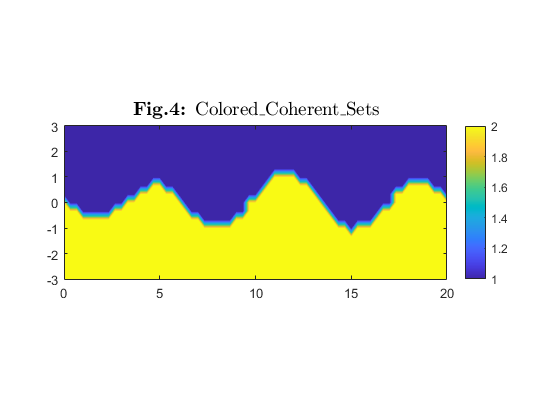

figure
contourf(VECRF.X,VECRF.Y,IDX,'edgecolor','none');
shading interp
title(['\textbf{Fig.4: }','Colored\_Coherent\_Sets'],'interpreter','latex','FontSize',14)
colorbar
pbaspect([2.5 1 1])

**Figure 5 - Eigenvalues**

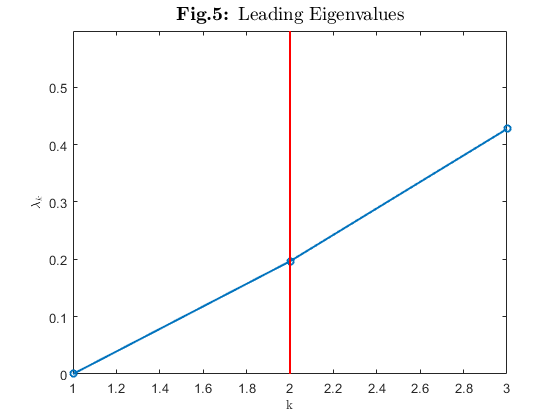

figure
plot(real(Eigval(1:end)),'-o','MarkerSize',5,'LineWidth',1.2)
xlim([1 NC+1])
ylim([0 Eigval(NC+5)])
hold on
plot([NC NC],[0 Eigval(NC+5)],'-r','LineWidth',1.5)
hold off
% scatter(NC,Eigval(NC),20,'d','MarkerFaceColor','r','MarkerEdgeColor','none');
xlabel('k','interpreter','latex','FontSize',10)
ylabel('$\lambda_{k}$','interpreter','latex','FontSize',10)
title(['\textbf{Fig.5: }','Leading Eigenvalues'],'interpreter','latex','FontSize',14)
box on

**Figure 6 - Advected Coherent Sets**

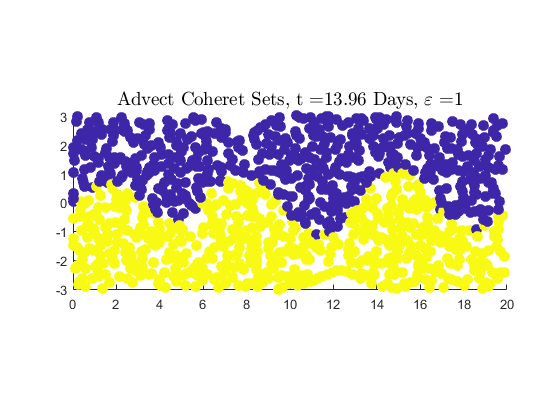

figure  
for N = 1 : length(VEC)
    scatter(A.X(N,:),A.Y(N,:),70,idx,'filled')
    hold on
    title(['Advect Coheret Sets,  t =',num2str((t(1)+(t(end)-t(1))*round(N/length(VEC),3))),...
        ' Days',', $\varepsilon$ =',num2str(eps)],'interpreter','latex',...
        'FontSize',14)
    axis([0 20 -3 3])
    hold off
    
    pbaspect([2.5 1 1])
    pause(0.1)
end